# Simulationsaufgabe Variante 3

## Systemparameter

clf;
clear all;
addpath('Simulationsaufgabe\');
J = 1;
D = 1.23;
DD = 1;
b = 0.01;
alpha_emax = 0.15;
m = 0;
dm = 0;
f_e = 4.9;

## Anfangsbedingungen


phi1_0 = 0;
phi2_0 = 0;
omega1_0 = 0;
omega2_0 = 0;

## Plot Config

ws = [2544 1920 1680 1600 1440 1366 1280 1024 768 512];
aspect_ratio = 16/9;
fwidth = 1280;
fheight = fwidth/aspect_ratio;

ic_deg = [phi1_0 phi2_0 omega1_0 omega2_0];
ic_rad = (2*pi/360)*ic_deg; % deg zu rad

delta = b/(2*J);
omega_a = sqrt(D/J); % Eigenwinkelfreq a
omega_b = sqrt((D+DD)/J); % Eigenwinnkelfreq b
f_a = omega_a/(2*pi); % Eigenfreq a
T_a = 1/f_a; % Periodendauer a

% --- Erregerstuff ---
M_emax = alpha_emax*D; % Erregermoment (max)
if f_e == 0
    T_e = inf;
else
    T_e = 1/f_e; % Erreger Periodendauer
end
omega_e = f_e*2*pi; % Erreggerfreq. zu Winkelfreq

Die *langsame* Frequenz ergibt sich durch $\omega_a = \sqrt{\frac{D}{J}}$, die *schnelle* Frequenz durch $\omega_b = \sqrt{\frac{D+DD}{J}}$ bzw. $\sqrt{\frac{2D}{J}}$ für den Fall gleicher Federkonstanten.

### Solving DGL

rz = 0.33;
dgl = @(t,u)dgl_1_24a(t, u, J, b, D, DD, M_emax, omega_e, m, rz);

% Abtasttheorem:
% Abtastrate n > 2*f
f = [f_e f_a];
n = 100*2.2*max(f);
tspan = linspace(0,10/max(f),ceil(n));

% fig = uifigure;
% d = uiprogressdlg(fig,'Title','Solving ...','Indeterminate','on');
% drawnow

[t,u] = ode45(dgl, tspan, ic_rad);

% close(d)

alpha_e = alpha_emax*sin(omega_e.*t);
phi1 = u(:,1);
phi2 = u(:,2);
omega1 = u(:,3);
omega2 = u(:,4);

## Plot

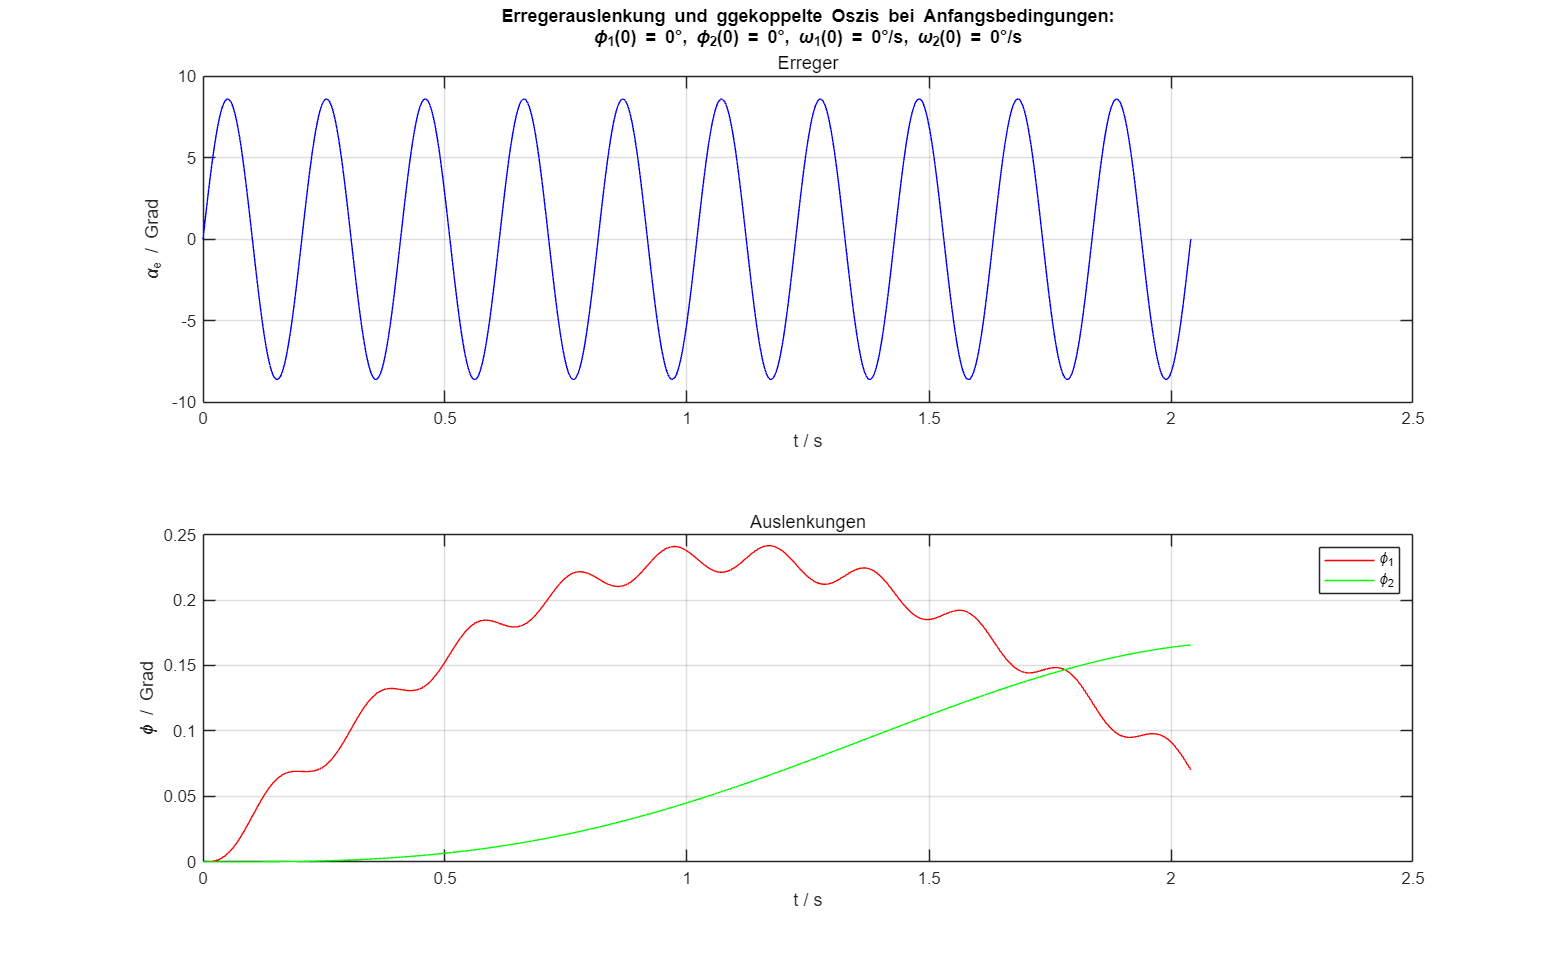

 
% Subplot erstellen
clf;
% staticfig = figure(1);
% staticfig.WindowState = 'maximized'; % Sorgt für ein direktes Vollbild
subplot(2,1,1);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos+[0 0 fwidth fheight]); % left bottom width height

% Erregerfrequenz und -auslenkung plotten und Plot formatieren
plot(t,alpha_e*360/(2*pi), 'b');
ylabel('\alpha_e / Grad')
xlabel('t / s')
title(sprintf('Erregerauslenkung und ggekoppelte Oszis bei Anfangsbedingungen:\n\\phi_1(0) = %d°, \\phi_2(0) = %d°, \\omega_1(0) = %d°/s, \\omega_2(0) = %d°/s', ic_deg));
subtitle('Erreger');
grid on

% Auslenkungen der beiden Räder plotten und Plot formatieren
subplot(2,1,2)
plot(t, phi1/(2*pi)*360, 'r');
hold on
plot(t, phi2/(2*pi)*360, 'g');
ylabel('\phi / Grad')
xlabel('t / s')
subtitle('Auslenkungen');
% zeroline = refline(0, 0); % Referenzlinie bei y=0 ...
% zeroline.Color = 'k'; % in schwarz
grid on
legend('\phi_1','\phi_2');

function du=dgl_1_24a(t,u,J,b,D,DD,Memax,we,m,rz)
    % Vektor u = [phi1, phi2, omega1, omega2)
    % omega1=dphi1, omega2=dphi2
     
    du = [;
        u(3);
        u(4);
        -(b/J).*u(3)-(D/J).*u(1)-(DD/J).*(u(1)-u(2))+(m*9.81*rz)/J.*sin(u(1))+(Memax/J).*sin(we.*t);
        -(b/J).*u(4)-(D/J).*u(2)-(DD/J).*(u(2)-u(1))
        ];
end

function res=ind_progr(fun)
    fig = uifigure;
    d = uiprogressdlg(fig, 'Title','Solving ...','Indeterminate','on');
    drawnow
    res=fun;
    close(d)
end